Loading the train data

addpath("lib/")
clear

k  = 100;
load("data.mat",'train_fea','train_gnd')
num_of_passes = 0;
accuracy=0;
[data_size,image_size] = size(train_fea);
image_size = sqrt(image_size);
test_index = randi(data_size,1,100);
train_index = 1:data_size;
train_index(test_index) = [];

train_face = train_fea(train_index,:)';
train_label = train_gnd(train_index,:);
test_face = train_fea(test_index,:)';
test_label = train_gnd(test_index,:);
train_size = size(train_index,2);
test_size = size(test_index,2);

Mean

train_mean = mean(train_face,2);
train_face = train_face - train_mean;

Eigen-faces

[eigen_faces,eigen_value,~] = svd(train_face'*train_face);
eigen_faces = normc(train_face*eigen_faces);
eigen_faces = eigen_faces(:,4:k+3); 
eigen_value = diag(eigen_value);
eigen_value = eigen_value(4:k+3)';

Projection

train_weights = eigen_faces' * train_face;

Training the model

nnOptions = {'lambda',0.0001,'hiddenLayers', [1000 500 250 100], 'activationFn', 'tanh', 'validPercent', 30, 'doNormalize', 1};
model = learnNN(train_weights',train_label,nnOptions);

Iteration     1 | Cost: 1.284704e+01
Iteration     2 | Cost: 4.730938e+00
Iteration     3 | Cost: 3.328701e+00
Iteration     4 | Cost: 2.493545e+00
Iteration     5 | Cost: 2.169334e+00
Iteration     6 | Cost: 1.655102e+00
Iteration     7 | Cost: 1.457054e+00
Iteration     8 | Cost: 1.184451e+00
Iteration     9 | Cost: 9.228967e-01
Iteration    10 | Cost: 7.961752e-01
Iteration    11 | Cost: 7.740550e-01
Iteration    12 | Cost: 5.454275e-01
Iteration    13 | Cost: 5.030147e-01
Iteration    14 | Cost: 4.758439e-01
Iteration    15 | Cost: 4.134874e-01
Iteration    16 | Cost: 3.566107e-01
Iteration    17 | Cost: 3.374208e-01
Iteration    18 | Cost: 3.136836e-01
Iteration    19 | Cost: 2.584193e-01
Iteration    20 | Cost: 1.700456e-01
Iteration    21 | Cost: 1.499026e-01
Iteration    22 | Cost: 1.395574e-01
Iteration    23 | Cost: 1.310146e-01
Iteration    24 | Cost: 1.249975e-01
Iteration    25 | Cost: 1.182110e-01
Iteration    26 | Cost: 1.106964e-01
Iteration    27 | Cost: 1.057208e-01
I

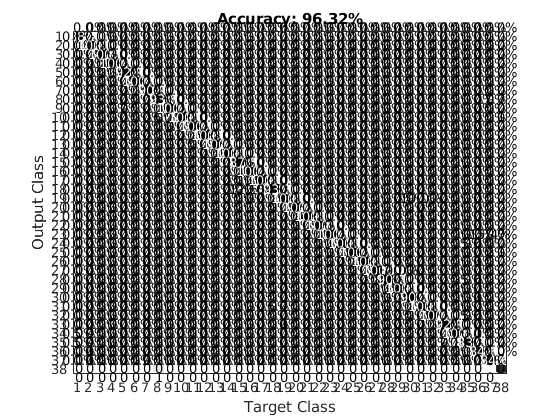

figure(1); cla(gca);
plotConfMat(model.confusion_valid);    

Testing the model

test_weights = eigen_faces'*(test_face - train_mean);
for i = 1:test_size
    pred = predictNN(test_weights(:,i)',model);
    if pred == test_label(i)
        accuracy=accuracy+1;
    end
end
disp(accuracy)

    98



Save model and eigen faces

image_mean = train_mean;
save('model.mat','model','eigen_faces','image_mean')